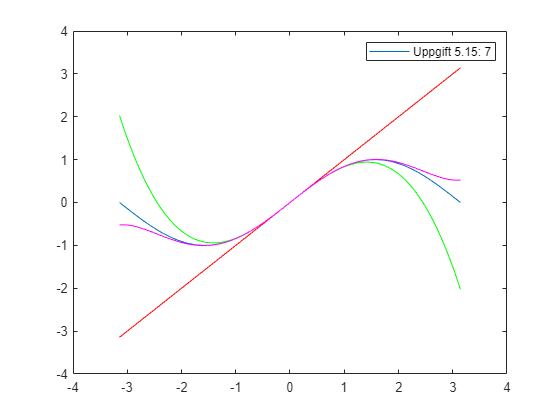

% 5.15 7
clear;
x = linspace(-pi, pi);
ySin = sin(x);
y1 = x;
y3 = x - (x.^3)/6;
y5 = y3 + (x.^5)/120;

plot(x,ySin)
hold on;
plot(x,y1,'-r');
plot(x,y3,'-g');
plot(x,y5,'-m');
legend("Uppgift 5.15: 7");

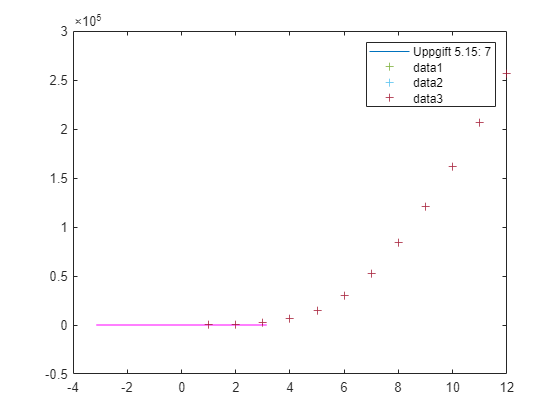

% 5.15 8 a
clear;
t = linspace(1,12,12);
N = [97 709 2698 6928 15242 29944 52902 83903 120612 161711 206247 257085];

plot(t,N,'+');
semilogy(t,N,'+');
loglog(t,N,'+');

% 5.15 8 b
clear;
t = [0 2 4 6 8 10 12 14];
N = [2 5 10 20 40 109 200 403]

N =      2     5    10    20    40   109   200   403


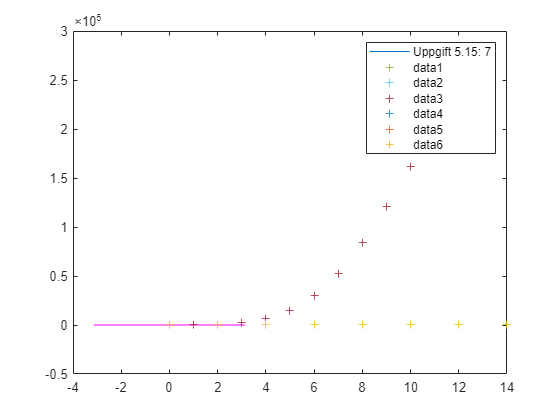

plot(t,N,'+');
semilogy(t,N,'+');
loglog(t,N,'+');

% 5.15 16
clear;
z = linspace(-50,50);
pA = z.^5 - 1.1;
pB = z.^2+3*z+4;
pC = z.^2+(-1+1i)*z+2-2i;

plot(z, pA);
hold on;
plot(z, pB);
plot(z, pC);

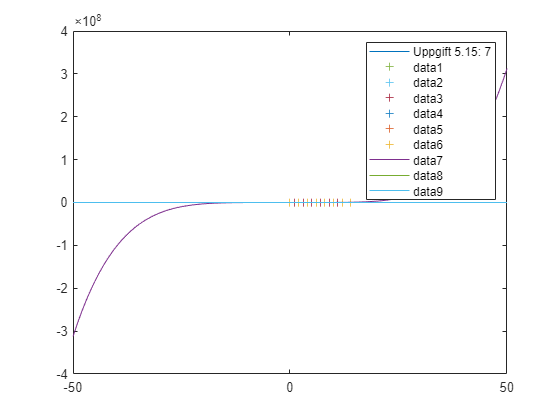

hold off;

[MinA, IndexA] = min(abs(pA))

MinA = 1.0671

IndexA = 51

[MinB, IndexB] = min(abs(pB))

MinB = 1.7502

IndexB = 49

[MinC, IndexC] = min(abs(pC))

MinC = 2.3016

IndexC = 51

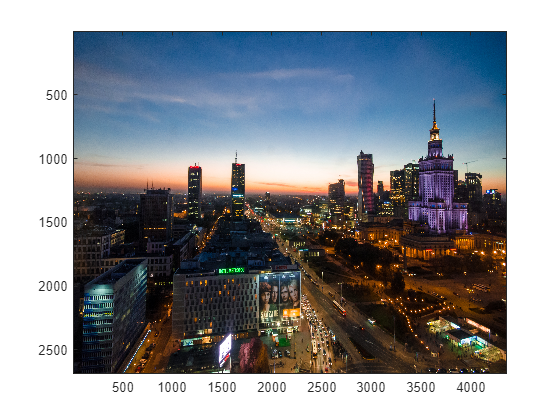

% 5.15 19
clear;
%[url_img, map] = imread('https://static.pexels.com/photos/14621/Warsaw-at-night-free-license-CC0.jpg');
A = imread('https://static.pexels.com/photos/14621/Warsaw-at-night-free-license-CC0.jpg');
%figure, imshow(url_img), title('Image from url')
imagesc(A);

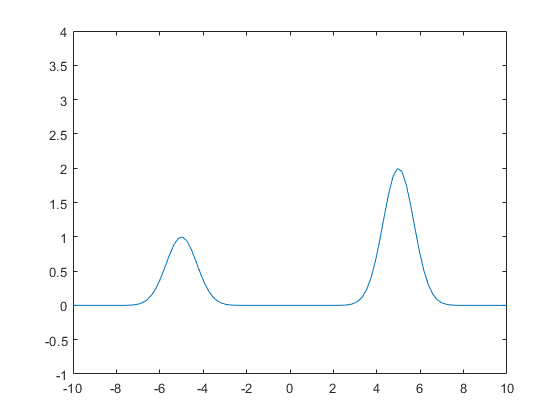

% 5.15 21
clear
x = linspace(-10,10);

f1 = @(x) exp(-(x+5).^2);
f2 = @(x) 2*exp(-(x-5).^2);

plot(x, f1(x) + f2(x))
axis([-10 10 -1 4])

frames = moviein(101);

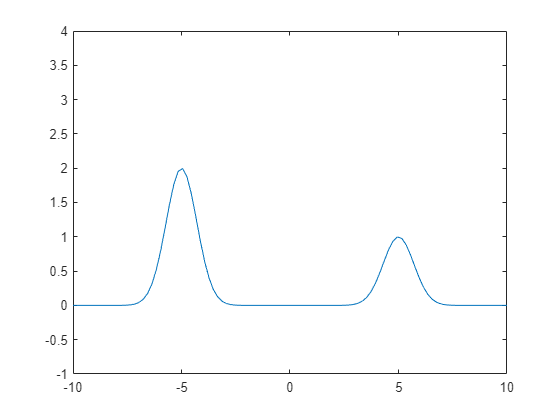

for i = 1:101
    t = 0.1*(i-1);
    plot(x, f1(x-t) + f2(x+t));
    axis([-10 10 -1 4])
    frames(:,i) = getframe;
end    
movie(frames, 10)

vidObj = VideoWriter('animering.avi');
open(vidObj);
writeVideo(vidObj,frames);

Unrecognized function or variable 'obj'.

close();


% 6.18 9
clear
x = input('Input your x: ')
y = input('Input your y: ')

v = [x, y];

if x == 0 && y > 0
    ang = pi/2;
elseif x == 0 && y < 0
    ang = -pi/2
elseif x > 0
    ang = atan(y/x);
elseif x < 0 || y >= 0
    ang = atan(y/x) + pi;
elseif x < 0 || y <= 0
    ang = atan(y/x) - pi;
end
ang
angle(x+i*y)

% 6.18 14
clear
f0 = 0;
f1 = 1;
fRes = f0 + f1;
counter = 2;
while fRes < 100000
    f0 = f1;
    f1 = fRes;
    fRes = f0 + f1;
    counter = counter+1;
end
counter
fRes

% 6.18 27 a
clear
v = [1 -2 -3 -4 2 3 4]
minsta = 1e30;
n = length(v);
for i = 1:n
    if v(i) < minsta
        minsta = v(i);
        pos = i;
    end
end
disp('Minsta värde'), disp(minsta)
disp('Position'), disp(pos)

% 6.18 27 b
clear
v = [1 -2 -3 -4 2 3 4]
storsta = 1e-30;
n = length(v);
for i = 1:n
    if v(i) > storsta
        storsta = v(i);
        pos = i;
    end
end
disp('Storsta värde'), disp(storsta)
disp('Position'), disp(pos)

% 6.18 27 c
clear
n = input('Input your rows: ')
m = input('Input your columness: ')
v = rand(n, m)
minsta = 1e30;
for i = 1:n %rows
    for j = 1:m %cols
        if v(i, j) < minsta
            minsta = v(i, j);
            pos = [i, j];
        end
    end
end
disp('Minsta värde'), disp(minsta)
disp('Position'), disp(pos)

% 6.18 27 d
clear
n = input('Input your rows: ')
m = input('Input your columness: ')
d = input('Input your depth: ')
v = rand(n, m, d)
minsta = 1e30;
for i = 1:n %rows
    for j = 1:m %cols
        for k = 1:d
            if v(i, j, k) < minsta
                minsta = v(i, j, k);
                pos = [i, j, k];
            end
        end
    end
end
disp('Minsta värde'), disp(minsta)
disp('Position'), disp(pos)